# Transformée(s) de Hough - Espaces de votes

## I. Modélisation de segments de droite

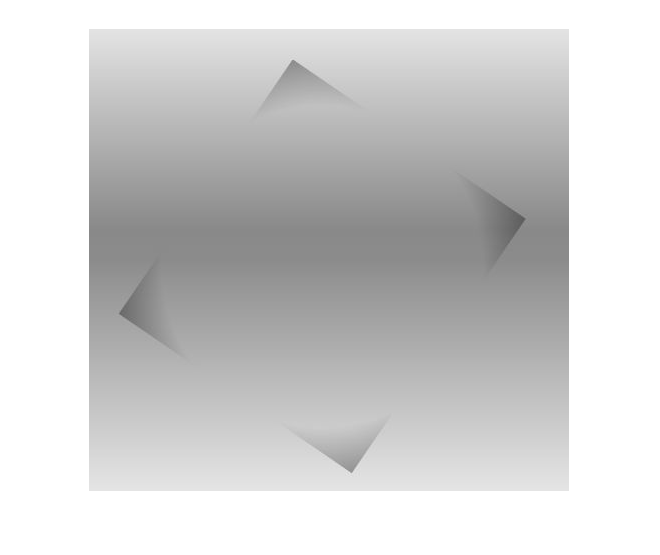

img=imread('TP03I01.jpg');
imshow(img);

img=double(img);
threshold=7;
BW=edge(img,'Prewitt',threshold);
imshow(BW);
[x, y]=size(BW);
diag = round(sqrt(x.^2 + y.^2));
V = zeros(diag,628);
for i=1:x
    for j=1:y
      if (BW(i,j)==1)
        for teta=1:628        
            ro=round(i*cos(teta/100) + j*sin(teta/100)); 
            if(ro> 0 && ro < diag)
                V(ro,teta)=V(ro,teta)+1;
            end
        end
      end
    end
end
figure();
imagesc(log(V+1));
colormap(gray(256));

## II. Reconnaissance de segments de droite

Identifiez les coordonnées des k points recevant le plus grand nombre de votes

figure();
subplot(2,3,1);
imagesc(img);
title("Image de base")
axis equal;
axis off;

%------------------------------K=1--------------------------------
V_bis =V;
k = 1;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max
[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,2);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=1")
hold off
axis equal;
axis off;
%------------------------------K=3--------------------------------
V_bis =V;
k = 3;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max
[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,3);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end 
title("K=3")
hold off
axis equal;
axis off;
%------------------------------K=4--------------------------------
V_bis =V;
k = 4;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max
[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,4);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=4")
hold off
axis equal;
axis off;
%------------------------------K=10--------------------------------
V_bis =V;
k = 10;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max
[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,5);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=10")
hold off
axis equal;
axis off;
%------------------------------K= 20--------------------------------
V_bis =V;
k = 20;
Liste_max = [];
for i=1:k
    [Vmax,idx]=max(V_bis);
    [Vmax, Vj] =max(Vmax);
    Vi = idx(Vj);
    Liste_max=[Liste_max; Vi Vj Vmax];
    V_bis(Vi, Vj) = 0;
end
Liste_max
[row_v,col_v] = size(V);
epsilum = 0.2;
droites =[];

for indice=1 : size(Liste_max,1)
    bool = 0;
    rho = Liste_max(indice,1);
    theta = Liste_max(indice,2);
    for x=1:x
            for y=1:y
                if BW(x,y) == 1
                    if abs(x*cos(theta/100)+y*sin(theta/100)-rho) < epsilum
                        if bool == 0
                            x1 = x;
                            y1 = y;
                            bool = 1;
                        end
                           x2 = x;
                           y2= y;                           
                    end
                end
            end
    end
   droites =[droites ; y1 y2 x1 x2]; % Y  = col = abscisses
   %X = row = ordonnÃ©es
   
end
subplot(2,3,6);
hold on
imagesc(img);
colormap(gray(256));
for i= 1:size(droites,1)
        plot(droites(i,1:2),droites(i,3:4),'r-');
end
title("K=20")
hold off
axis equal;
axis off;

## III. Back projection of the Radon transform

image2= double(imread('TP03I02.bmp'));
I = zeros(468,500);
for r = 1:468
    for c = 1:500
        for theta = 1:628
            temp1 = ceil(r*cos(theta/100)+c*sin(theta/100));           
            if( temp1 >0 && temp1 < 968)
                I(r,c) = I(r,c) + image2(temp1,theta);
            end
        end
    end
    disp(r);
end
figure();
imagesc(I);
colormap(gray(256));

## IV Generalized Hough Transform  

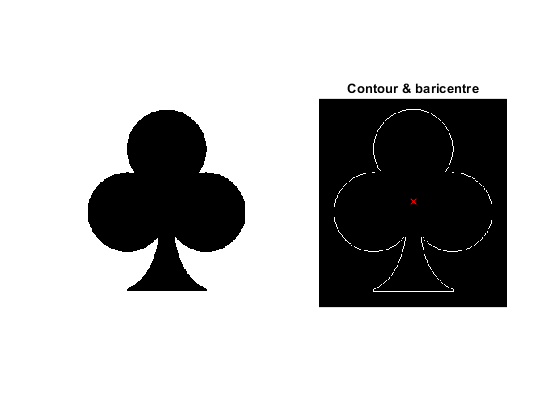

img=imread('TP03I03.bmp');
img=img(:,:,1)>0;
figure();
subplot(1,2,1)
imshow(img)
[r3,c3]=size(img);
Im_contour=zeros(r3,c3);
% Recovering information about the contour
[C, N]=contour(img);
for i=1:N
    Im_contour(C(i,1),C(i,2))=1;
end
subplot(1,2,2)
imshow(Im_contour);
% Initialize the model :
% row = beta value * 100
% column = order number of the couple (alpha, distance)
% third dimension: for 1 = alpha, for 2 = distance
H=zeros(round(100*2*pi),N,2);
% Calculation of the coordinates of the barycenter
[xo,yo]=barycentre(img);
hold on
scatter(yo,xo,'rx');
title("Contour & baricentre");
hold off

% Browsing the points on the contour
for i=1:N
 % calculation of b=beta for the ith point of the contour
 b=beta(C,img,i);
 b=round(b);
 % search for the first "empty" column in the table on the line beta
 k=1;
 while H(b+1,k,2)~=0
    k=k+1;
 end
 % record of the value of alpha and the distance on the b+1 row and the kth column of H
 a = alpha(C, i, img);
 d=distance(xo,yo,b,k);
 H(b+1,k,1)=a;
 H(b+1,k,2)=d;
end 

a = 1.5619

a = 1.5531

a = 1.5443

a = 1.5354

a = 1.5266

a = 1.5177

a = 1.5089

a = 1.5001

a = 1.4913

a = 1.4817

a = 1.4729

a = 1.4641

a = 1.4552

a = 1.4453

a = 1.4365

a = 1.4276

a = 1.4175

a = 1.4086

a = 1.3998

a = 1.3893

a = 1.3805

a = 1.3698

a = 1.3610

a = 1.3501

a = 1.3392

a = 1.3303

a = 1.3191

a = 1.3078

a = 1.2989

a = 1.2874

a = 1.2757

a = 1.2640

a = 1.2520

a = 1.2400

a = 1.2278

a = 1.2154

a = 1.2029

a = 1.1903

a = 1.1775

a = 1.1737

a = 1.1607

a = 1.1475

a = 1.1433

a = 1.1299

a = 1.1163

a = 1.1118

a = 1.0979

a = 1.0931

a = 1.0790

a = 1.0740

a = 1.0689

a = 1.0543

a = 1.0490

a = 1.0435

a = 1.0285

a = 1.0228

a = 1.0169

a = 1.0015

a = 0.9954

a = 0.9891

a = 0.9828

a = 0.9763

a = 0.9697

a = 0.9630

a = 0.9464

a = 0.9393

a = 0.9322

a = 0.9248

a = 0.9174

a = 0.9098

a = 0.9020

a = 0.9041

a = 0.8961

a = 0.8878

a = 0.8795

a = 0.8709

a = 0.8622

a = 0.8533

a = 0.8546

a = 0.8453

a = 0.8359

a = 0.8262

a = 0.8270

a = 0.8170

a = 0.8067

a = 0.8071

a = 0.7964

a = 0.7966

a = 0.7854

a = 0.7739

a = 0.7736

a = 0.7734

a = 0.7610

a = 0.7604

a = 0.7474

a = 0.7465

a = 0.7454

a = 0.7188

a = 0.7066

a = 0.6947

a = 0.6832

a = 0.6720

a = 0.6610

a = 0.6504

a = 0.6401

a = 0.6435

a = 0.6336

a = 0.6107

a = 0.6015

a = 0.5924

a = 0.5836

a = 0.5751

a = 0.5667

a = 0.5586

a = 0.5507

a = 0.5430

a = 0.5228

a = 0.5155

a = 0.5085

a = 0.5016

a = 0.4825

a = 0.4761

a = 0.4698

a = 0.4515

a = 0.4456

a = 0.4277

a = 0.4223

a = 0.4169

a = 0.3998

a = 0.3948

a = 0.3781

a = 0.3617

a = 0.3573

a = 0.3414

a = 0.3256

a = 0.3102

a = 0.3065

a = 0.2915

a = 0.2767

a = 0.2621

a = 0.2478

a = 0.2337

a = 0.2199

a = 0.2063

a = 0.1930

a = 0.1799

a = 0.1688

a = 0.1560

a = 0.1435

a = 0.1326

a = 0.1203

a = 0.1083

a = 0.0975

a = 0.0858

a = 0.0751

a = 0.0637

a = 0.0531

a = 0.0425

a = 0.0316

a = 0.0210

a = 0.0105

a = 0

a = -0.0104

a = -0.0208

a = -0.0312

a = -0.0412

a = -0.0515

a = -0.0618

a = -0.0720

a = -0.0823

a = -0.0925

a = -0.1027

a = -0.1129

a = -0.1231

a = -0.1332

a = -0.1433

a = -0.1534

a = -0.1635

a = -0.1735

a = -0.1835

a = -0.1934

a = -0.2033

a = -0.2132

a = -0.2230

a = -0.2328

a = -0.2450

a = -0.2548

a = -0.2645

a = -0.2742

a = -0.2866

a = -0.2963

a = -0.3059

a = -0.3186

a = -0.3281

a = -0.3410

a = -0.3505

a = -0.3635

a = -0.3730

a = -0.3862

a = -0.3956

a = -0.4089

a = -0.4224

a = -0.4317

a = -0.4453

a = -0.4590

a = -0.4729

a = -0.4869

a = -0.4960

a = -0.5101

a = -0.5243

a = -0.5386

a = -0.5530

a = -0.5586

a = -0.5733

a = -0.5880

a = -0.6028

a = -0.6178

a = -0.6240

a = -0.6392

a = -0.6457

a = -0.6610

a = -0.6765

a = -0.6834

a = -0.6990

a = -0.7062

a = -0.7135

a = -0.7295

a = -0.7370

a = -0.7532

a = -0.7610

a = -0.7690

a = -0.7771

a = -0.7937

a = -0.8021

a = -0.8106

a = -0.8193

a = -0.8281

a = -0.8452

a = -0.8543

a = -0.8635

a = -0.8729

a = -0.8824

a = -0.8921

a = -0.9020

a = -0.9120

a = -0.9222

a = -0.9325

a = -0.9430

a = -0.9536

a = -0.9644

a = -0.9754

a = -0.9790

a = -0.9904

a = -1.0019

a = -1.0137

a = -1.0256

a = -1.0304

a = -1.0427

a = -1.0552

a = -1.0608

a = -1.0738

a = -1.0870

a = -1.0935

a = -1.1071

a = -1.1142

a = -1.1284

a = -1.1361

a = -1.1509

a = -1.1593

a = -1.1747

a = -1.1839

a = -1.1935

a = -1.2100

a = -1.2205

a = -1.2315

a = -1.2431

a = -1.2552

a = -1.2737

a = -1.2870

a = -1.3009

a = -1.2954

a = -1.3102

a = -1.3258

a = -1.3521

a = -1.3567

a = -1.3612

a = -1.3654

a = -1.3695

a = -1.3734

a = -1.3772

a = -1.3623

a = -1.3662

a = -1.3698

a = -1.3734

a = -1.3768

a = -1.3633

a = -1.3668

a = -1.3701

a = -1.3734

a = -1.3608

a = -1.3641

a = -1.3673

a = -1.3704

a = -1.3587

a = -1.3618

a = -1.3648

a = -1.3537

a = -1.3567

a = -1.3597

a = -1.3491

a = -1.3521

a = -1.3420

a = -1.3450

a = -1.3479

a = -1.3382

a = -1.3412

a = -1.3319

a = -1.3348

a = -1.3258

a = -1.3287

a = -1.3201

a = -1.3230

a = -1.3146

a = -1.3065

a = -1.3095

a = -1.3016

a = -1.2940

a = -1.2970

a = -1.2896

a = -1.2824

a = -1.2754

a = -1.2784

a = -1.2716

a = -1.2649

a = -1.2584

a = -1.2521

a = -1.2460

a = -1.2400

a = -1.2341

a = -1.2284

a = -1.2228

a = -1.2174

a = -1.2088

a = -1.2036

a = -1.1985

a = -1.1903

a = -1.1854

a = -1.1773

a = -1.1727

a = -1.1648

a = -1.1603

a = -1.1526

a = -1.1483

a = -1.1517

a = -1.1551

a = -1.1626

a = -1.1703

a = -1.1779

a = -1.1856

a = -1.1934

a = -1.2012

a = -1.2091

a = -1.2170

a = -1.2249

a = -1.2329

a = -1.2410

a = -1.2490

a = -1.2572

a = -1.2653

a = -1.2736

a = -1.2818

a = -1.2901

a = -1.2985

a = -1.3068

a = -1.3152

a = -1.3237

a = -1.3322

a = -1.3407

a = -1.3493

a = -1.3579

a = -1.3665

a = -1.3751

a = -1.3838

a = -1.3925

a = -1.4013

a = -1.4100

a = -1.4188

a = -1.4276

a = -1.4365

a = -1.4453

a = -1.4542

a = -1.4631

a = -1.4720

a = -1.4809

a = -1.4899

a = -1.4988

a = -1.5078

a = -1.5168

a = -1.5258

a = -1.5348

a = -1.5438

a = -1.5528

a = -1.5618